Can signal density explain other quantities besides the asymptotic SNR ratio?

In this iteration I removed all the conditions on session selection that I had earlier. Now the only condition is that the number of neurons must be larger than 200 (150 before) and the number of trials must be greater than 40 (15 before) per direction. When I originally selected the 107 sessions, the conditions were neurons > 150, trials > 15 and mean decoding error < 6cm. So the change here is to make the first two conditions more stringent, and the result is that 71 sessions pass the conditions (and only 10 mice). It looks like this change really improves the correlations of several of the variables.

Initialization:

org = Org;
org.load_definitions;

org.session_properties_dataset;

Here is the correspondence with the asymptotic SNR ratio:

Using only 71 out of 107 sessions
Mouse-aggregated correlations signal_density vs. asymp_ratio: adj. R^2 = 0.930
Pearson: -0.968, p = 4.195672e-06, ***
Spearman: -0.976, p = 0.000000e+00, ***
Kendall: -0.911, p = 2.976190e-05, ***


Using only 71 out of 107 sessions
Sessionwise correlations signal_density vs. asymp_ratio: adj. R^2 = 0.607
Pearson: -0.783, p = 7.684910e-16, ***
Spearman: -0.840, p = 0.000000e+00, ***
Kendall: -0.652, p = 9.656072e-16, ***


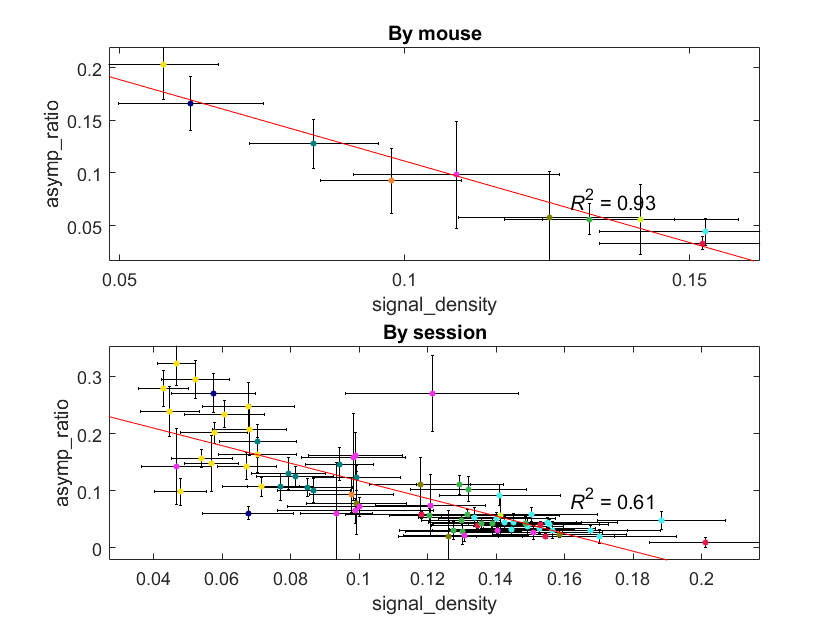

plot_pair(org, 'signal_density', 'asymp_ratio');

We can try the ratio of N50 (real/shuffled) (95% confidence intervals, with uncertainty propagated from the curve fitting):

Using only 71 out of 107 sessions
Mouse-aggregated correlations signal_density vs. N50_ratio: adj. R^2 = 0.004
Pearson: -0.338, p = 3.393891e-01, n.s
Spearman: -0.370, p = 2.956041e-01, n.s
Kendall: -0.200, p = 4.843127e-01, n.s


Using only 71 out of 107 sessions
Sessionwise correlations signal_density vs. N50_ratio: adj. R^2 = 0.089
Pearson: -0.319, p = 6.673511e-03, **
Spearman: -0.385, p = 9.280416e-04, ***
Kendall: -0.255, p = 1.677886e-03, **


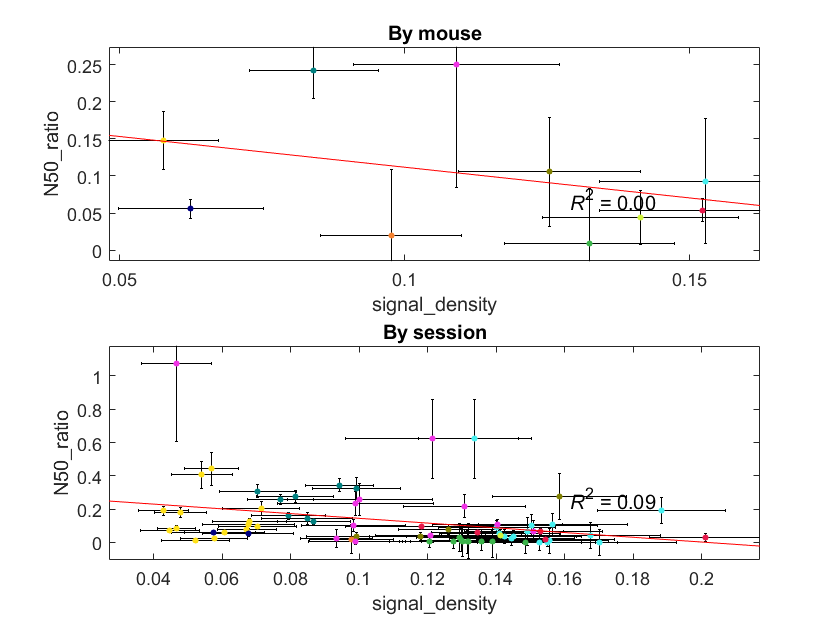

plot_pair(org, 'signal_density', 'N50_ratio');

Using signal density with the ratio of I0N from the decoding results:

Using only 71 out of 107 sessions
Mouse-aggregated correlations signal_density vs. I0N_ratio: adj. R^2 = 0.073
Pearson: -0.419, p = 2.277488e-01, n.s
Spearman: -0.394, p = 2.628868e-01, n.s
Kendall: -0.244, p = 3.807198e-01, n.s


Using only 71 out of 107 sessions
Sessionwise correlations signal_density vs. I0N_ratio: adj. R^2 = 0.090
Pearson: -0.320, p = 6.453055e-03, **
Spearman: -0.400, p = 5.418564e-04, ***
Kendall: -0.270, p = 8.978901e-04, ***


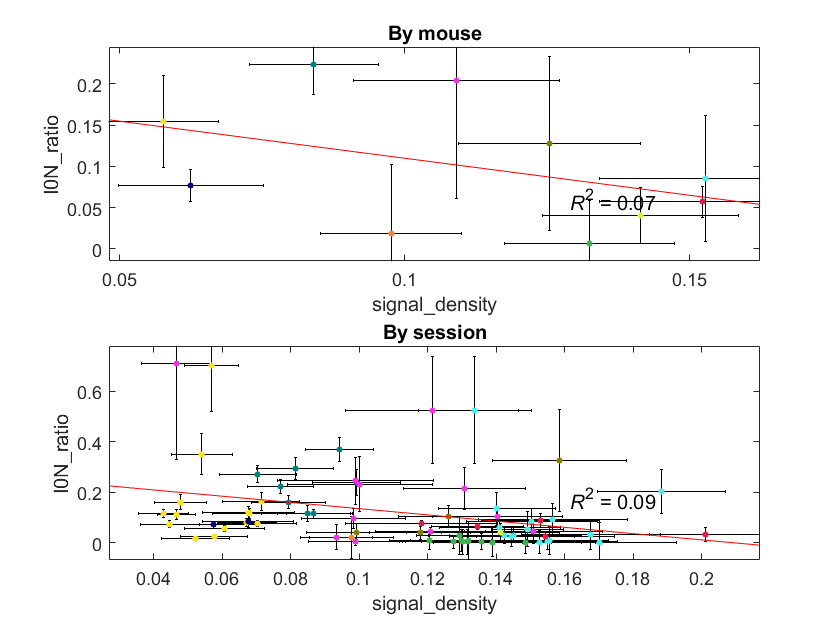

plot_pair(org, 'signal_density', 'I0N_ratio');

Signal density with the IMSE ratio at 150 neurons:

Using only 71 out of 107 sessions
Mouse-aggregated correlations signal_density vs. IMSE_150_ratio: adj. R^2 = 0.328
Pearson: -0.635, p = 4.871625e-02, *
Spearman: -0.503, p = 1.433668e-01, n.s
Kendall: -0.289, p = 2.912483e-01, n.s


Using only 71 out of 107 sessions
Sessionwise correlations signal_density vs. IMSE_150_ratio: adj. R^2 = 0.011
Pearson: -0.158, p = 1.890097e-01, n.s
Spearman: -0.100, p = 4.050226e-01, n.s
Kendall: -0.043, p = 5.953391e-01, n.s


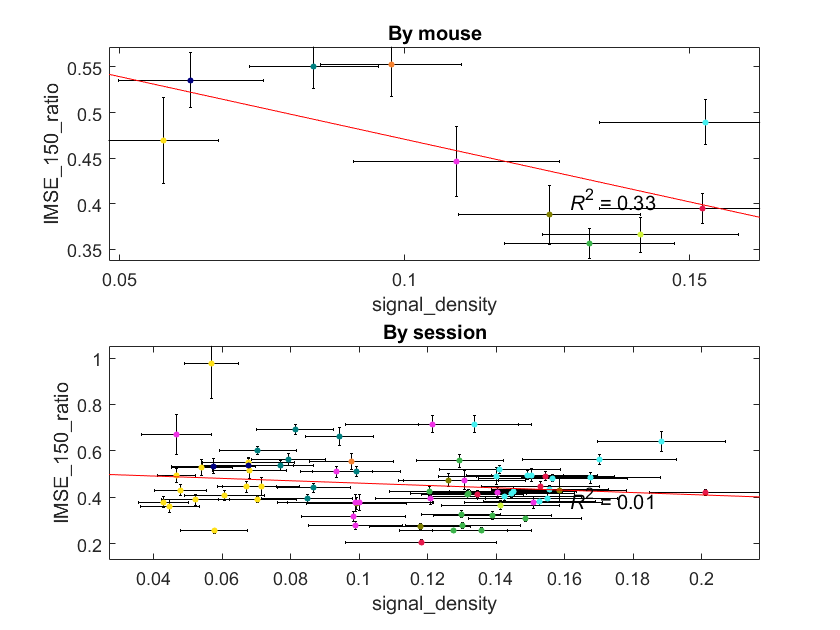

plot_pair(org, 'signal_density', 'IMSE_150_ratio');

Signal density with 1/N50

Using only 71 out of 107 sessions
Mouse-aggregated correlations signal_density vs. invN50: adj. R^2 = -0.099
Pearson: 0.151, p = 6.778130e-01, n.s
Spearman: 0.115, p = 7.588331e-01, n.s
Kendall: 0.111, p = 7.274895e-01, n.s


Using only 71 out of 107 sessions
Sessionwise correlations signal_density vs. invN50: adj. R^2 = -0.002
Pearson: -0.109, p = 3.667282e-01, n.s
Spearman: -0.216, p = 6.978284e-02, n.s
Kendall: -0.154, p = 5.860215e-02, n.s


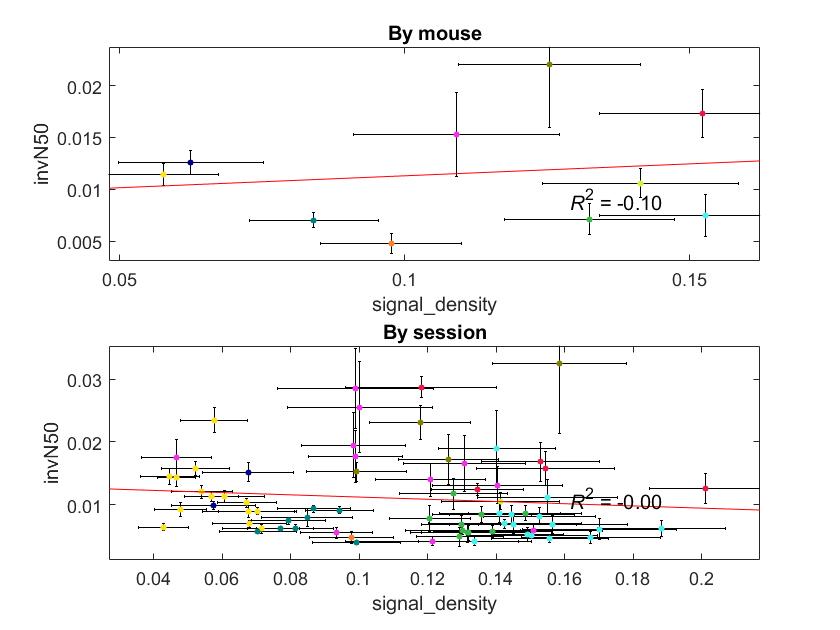

plot_pair(org, 'signal_density', 'invN50');

This is the relationship between cos^2 overlap and N50 that I sent before, it does look significant, but likely not the only factor.

This plot was supposed to be analogous to the one with gamma from Panzeri. The area of the cos^2 for the 5 largest eigenvectors was meant to be a more principled way to measure the overlap between signal and noise directions in N-dimensions. Gamma only does it for 2 dimensions, and uses random projections onto subgroups of neurons, but the goal of the cos^2 area and gamma is the same.

The inverse of N50 is proportional to the added amount of input noise in the model equaltion I(n)=I0*n/(1+n/N) (see equation 1 in Moreno-Bote 2014). Therefore, N50 is a measure of the information-limiting effect due to correlations.

Using only 71 out of 107 sessions
Mouse-aggregated correlations cos2_area_5 vs. invN50: adj. R^2 = 0.112
Pearson: 0.459, p = 1.821979e-01, n.s
Spearman: 0.600, p = 7.311988e-02, n.s
Kendall: 0.422, p = 1.083135e-01, n.s


Using only 71 out of 107 sessions
Sessionwise correlations cos2_area_5 vs. invN50: adj. R^2 = 0.139
Pearson: 0.389, p = 7.932826e-04, ***
Spearman: 0.523, p = 2.916751e-06, ***
Kendall: 0.353, p = 1.404032e-05, ***


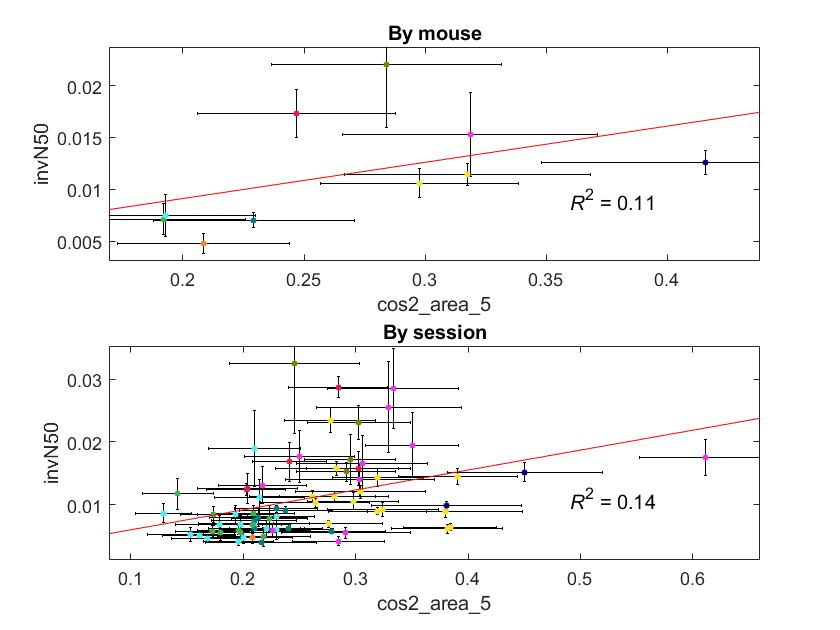

plot_pair(org,'cos2_area_5', 'invN50');

Using only 71 out of 107 sessions
Mouse-aggregated correlations cos2_area_5 vs. I0N_ratio: adj. R^2 = -0.050
Pearson: 0.259, p = 4.700212e-01, n.s
Spearman: 0.418, p = 2.324181e-01, n.s
Kendall: 0.333, p = 2.163735e-01, n.s


Using only 71 out of 107 sessions
Sessionwise correlations cos2_area_5 vs. I0N_ratio: adj. R^2 = 0.139
Pearson: 0.388, p = 8.165115e-04, ***
Spearman: 0.435, p = 1.510922e-04, ***
Kendall: 0.287, p = 4.168427e-04, ***


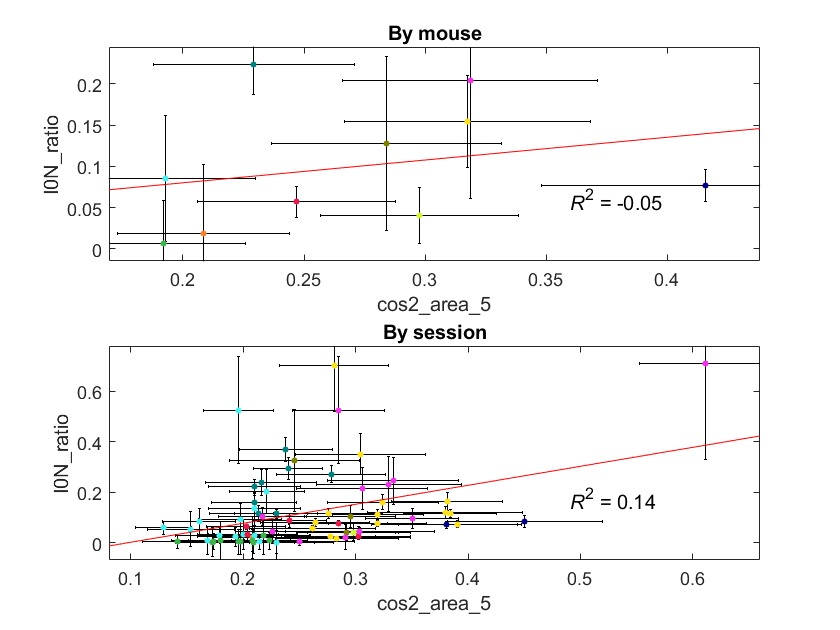

plot_pair(org,'cos2_area_5', 'I0N_ratio');

This is the relationship between the asymptotic ratio and the I0N ratio.

Using only 71 out of 107 sessions
Mouse-aggregated correlations asymp_ratio vs. I0N_ratio: adj. R^2 = 0.102
Pearson: 0.449, p = 1.932407e-01, n.s
Spearman: 0.503, p = 1.433668e-01, n.s
Kendall: 0.333, p = 2.163735e-01, n.s


Using only 71 out of 107 sessions
Sessionwise correlations asymp_ratio vs. I0N_ratio: adj. R^2 = 0.042
Pearson: 0.236, p = 4.723061e-02, *
Spearman: 0.373, p = 1.360399e-03, **
Kendall: 0.253, p = 1.856771e-03, **


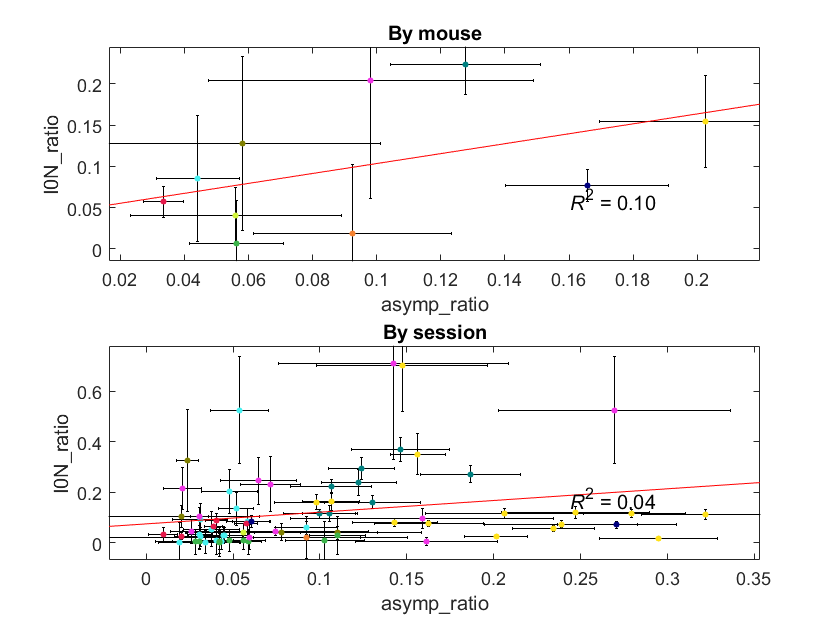

plot_pair(org, 'asymp_ratio', 'I0N_ratio');

This is the relationship between the asymptotic SNR (not the ratio, just in the real data) and the I0N value. It looks like there is a good trend except for a few distractor sessions (as above, the confidence region is larger than the value itself). This R^2 needs to be good to argue for the validity of Figure 3. In Figure 3 I am currently removing the distractor sessions from the R^2 calculation and it is = 0.5

Using only 71 out of 107 sessions
Mouse-aggregated correlations asymp_snr vs. I0N: adj. R^2 = 0.794
Pearson: 0.904, p = 3.323948e-04, ***
Spearman: 0.891, p = 1.380267e-03, **
Kendall: 0.733, p = 2.212853e-03, **


Using only 71 out of 107 sessions
Sessionwise correlations asymp_snr vs. I0N: adj. R^2 = 0.453
Pearson: 0.679, p = 7.857710e-11, ***
Spearman: 0.650, p = 8.453635e-10, ***
Kendall: 0.469, p = 7.797761e-09, ***


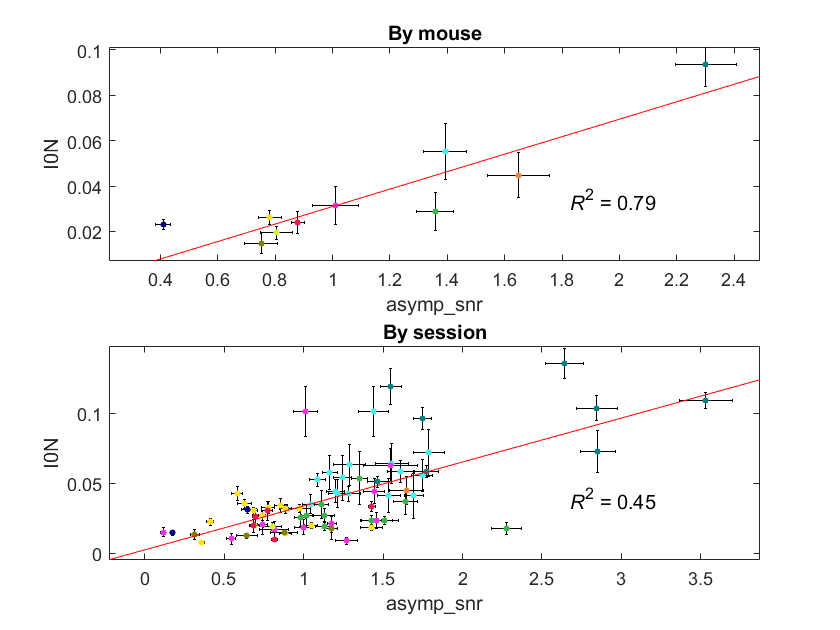

plot_pair(org, 'asymp_snr', 'I0N');

**New result:** 

The area between the shuffed cos^2 overlap and the real cos^2 overlap predicts 1/N50 quite well, when we use the 71 sessions. I think this is a good correspondence to show instead of using gamma. 

Using only 71 out of 107 sessions
Mouse-aggregated correlations cos2_area vs. invN50: adj. R^2 = 0.469
Pearson: 0.727, p = 1.722400e-02, *
Spearman: 0.721, p = 2.419459e-02, *
Kendall: 0.556, p = 2.860946e-02, *


Using only 71 out of 107 sessions
Sessionwise correlations cos2_area vs. invN50: adj. R^2 = 0.204
Pearson: 0.464, p = 4.663950e-05, ***
Spearman: 0.342, p = 3.507461e-03, **
Kendall: 0.237, p = 3.571883e-03, **


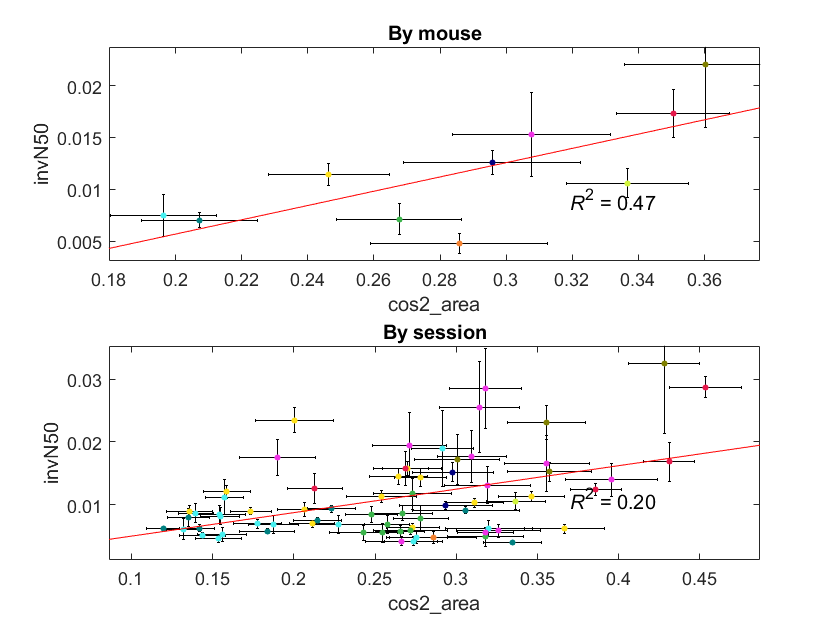

plot_pair(org, 'cos2_area', 'invN50');

function plot_pair(org, var1, var2)
figure;
subplot(2,1,1);
org.correlogram(var1, var2, true); title('By mouse');
subplot(2,1,2);
org.correlogram(var1, var2, false); title('By session');
end